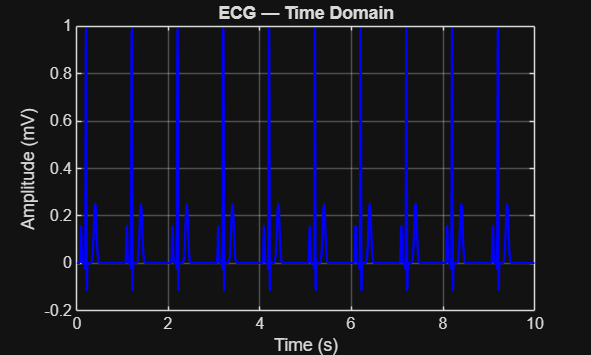

% Generate ECG signal (same as before)
duration   = 10;
fs         = 1000;
beat_every = 1;

t   = 0 : 1/fs : duration;
tau = mod(t, beat_every);

a1 =  0.25;  b1 = 0.09;   c1 = 0.015;
a2 = -0.2;   b2 = 0.185;  c2 = 0.008;
a3 =  1.6;   b3 = 0.20;   c3 = 0.012;
a4 = -0.4;   b4 = 0.215;  c4 = 0.008;
a5 =  0.4;   b5 = 0.40;   c5 = 0.04;

scale = 1 / 1.6;

ecg = scale * ( a1 .* exp(-((tau - b1)./c1).^2) + ...
                a2 .* exp(-((tau - b2)./c2).^2) + ...
                a3 .* exp(-((tau - b3)./c3).^2) + ...
                a4 .* exp(-((tau - b4)./c4).^2) + ...
                a5 .* exp(-((tau - b5)./c5).^2) );
% ---- Plot ----
figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('ECG — Time Domain');
grid on;



% ---- Package for Simulink ----
ecg_sim.time            = t';               % column vector
ecg_sim.signals.values  = ecg';             % column vector
ecg_sim.signals.dimensions = 1;
